%% Generate data
fun_gaussian = @(A,xy) A(1) * exp( - ( (xy{1}-A(5)).^2 / (2*A(3)^2) + (xy{2}-A(6)).^2 / (2*A(4)^2) )  ) + A(2) + A(1) / A(7) * randn(size(xy{1},1),size(xy{1},2));
    % A = [amplitude, ofset, sx, sy, x0, y0, s2n]

%% Data setup
len_x = 512;
len_y = 512;
xy = {};
x = (1:1:len_x) ;
y = (1:1:len_y)';
[xy{1}, xy{2}] = meshgrid(x,y);
A = [2 0 15 15 250 245 0.5];
nxy = fun_gaussian(A,xy);

%% Fourier transform
nxyt = fft2(nxy); 
rad_x = 50; rad_y = 50; cen_x = len_x/2+1; cen_y = len_y/2;
nxyt = fftshift(nxyt);
nxyt2 = nxyt;
for i = 1:len_y
    for j = 1:len_x
        if ((i-cen_y)/rad_y)^2 + ((j-cen_x)/rad_x)^2 > 1, nxyt2(i,j) = 0; end
    end
end
nxy2 = ifft2(ifftshift(nxyt));


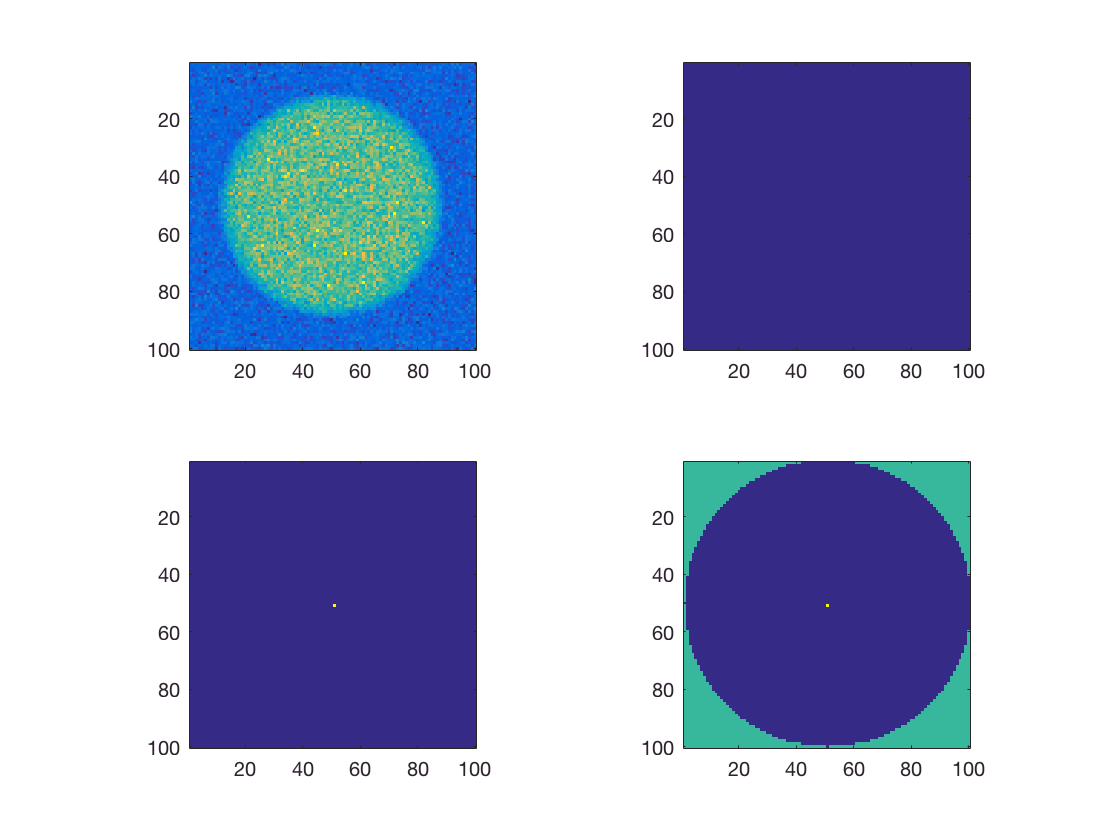

%% Plotting
figure;
%subplot(1,1,1); imagesc(abs(nxyt));
subplot(2,2,1); imagesc(nxy); axis image;
subplot(2,2,2); imagesc(abs(nxy2)); axis image;
subplot(2,2,3); imagesc(abs(nxyt)); axis image;
subplot(2,2,4); imagesc(abs(nxyt2)); axis image;